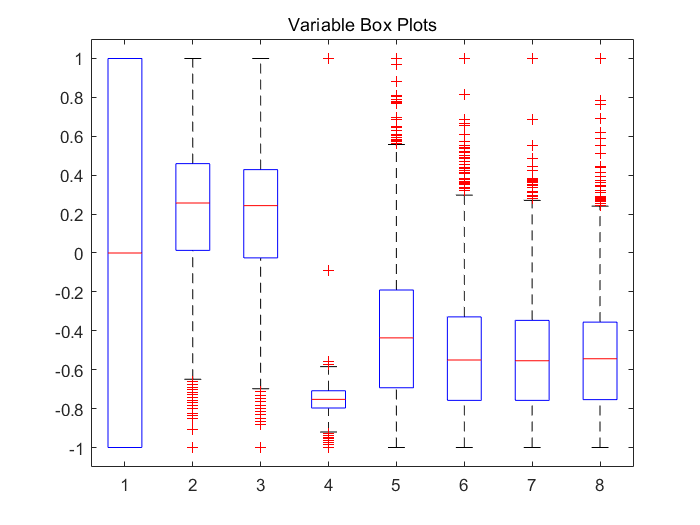

% import data: 4177 x 8 
[y, A] = libsvmread('datasets/abalone.txt'); 
[n,p]  = size(A);
A = full(A);
q = ceil(0.75 * n);

% split into training set and testing set
A_train = A(1:q,:);
A_test  = A(q+1:end,:);
y_train = y(1:q,:);
y_test  = y(q+1:end,:);

% box plot
figure;
boxplot(A_train);
title('Variable Box Plots');
% using frequent Lasso 
% standarlize is not needed since the data has been scaled

[LassoBetaEstimates,FitInfo] = lasso(A_train,y_train,'Standardize',false);

%prediction and MSE
yFLasso_train = FitInfo.Intercept + A_train*LassoBetaEstimates;
fmseLasso_train = sqrt(mean((y_train - yFLasso_train).^2,1));
yFLasso_test = FitInfo.Intercept + A_test*LassoBetaEstimates;
fmseLasso_test = sqrt(mean((y_test - yFLasso_test).^2,1));

hax = lassoPlot(LassoBetaEstimates,FitInfo,'PlotType','L1');

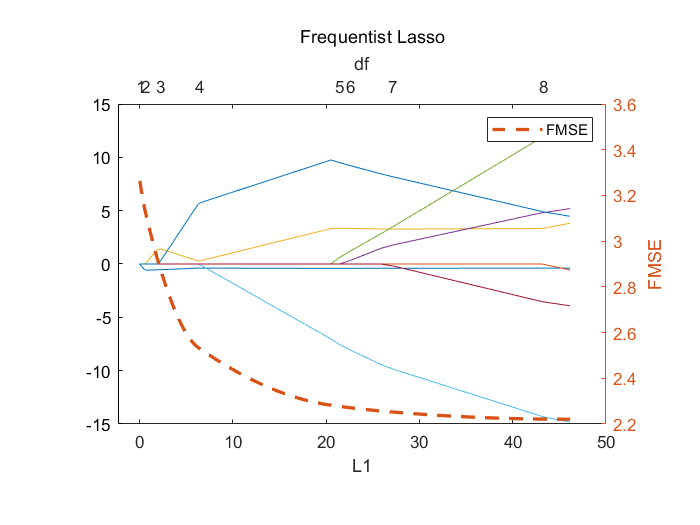

L1Vals = hax.Children.XData;
yyaxis right;
h_train = plot(L1Vals,fmseLasso_train,'LineWidth',2,'LineStyle','--');
legend(h_train,'FMSE');
%legend();
ylabel('FMSE');
title('Frequentist Lasso');

% using Bayesian Lasso 
lambda = FitInfo.Lambda * n./ sqrt(FitInfo.MSE);
PriorMdl = bayeslm(p,'ModelType','lasso');
numlambda = numel(lambda);
% Preallocate
BayesLassoCoefficients = zeros(p+1,numlambda);
BayesLassoCI95 = zeros(p+1,2,numlambda);
fmseBayesLasso_train = zeros(numlambda,1);
fmseBayesLasso_test = zeros(numlambda,1);
BLCPlot = zeros(p+1,numlambda);

% Estimate and forecast
rng(42); % For reproducibility
for j = 1:numlambda
    %fprintf('running lamda %.3e\n',lambda)
    PriorMdl.Lambda = lambda(j);
    [EstMdl,Summary] = estimate(PriorMdl,A_train,y_train,'Display',false);
    
    % mean for beta
    BayesLassoCoefficients(:,j) = Summary.Mean(1:(end - 1));
    BLCPlot(:,j) = Summary.Mean(1:(end - 1));
    BayesLassoCI95(:,:,j) = Summary.CI95(1:(end - 1),:);
    
    % credible interval includes 0, then set the corresponding posterior mean to zero.
    idx = BayesLassoCI95(:,2,j) > 0 & BayesLassoCI95(:,1,j) <= 0;
    BLCPlot(idx,j) = 0;
    
    % choose mean for forecastting
    yFBayesLasso_train = forecast(EstMdl,A_train);
    fmseBayesLasso_train(j) = sqrt(mean((y_train - yFBayesLasso_train).^2));
    
    % test
    yFBayesLasso_test = forecast(EstMdl,A_test);
    fmseBayesLasso_test(j) = sqrt(mean((y_test - yFBayesLasso_test).^2));
end

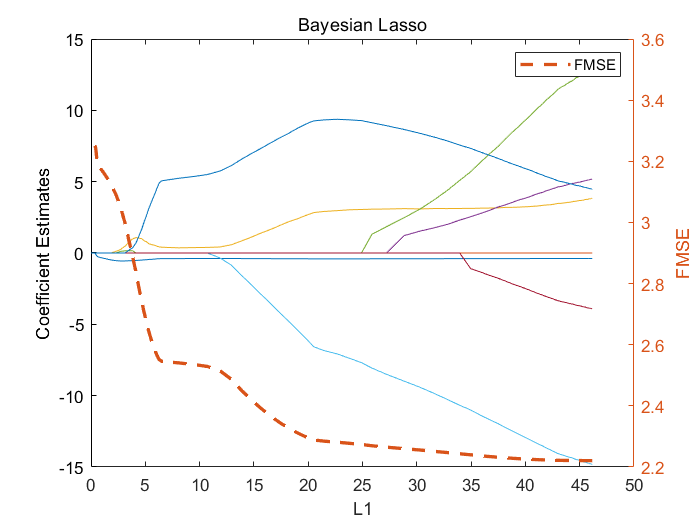


figure;
plot(L1Vals,BLCPlot(2:end,:))
xlabel('L1');
ylabel('Coefficient Estimates');
yyaxis right;
h_train = plot(L1Vals,fmseBayesLasso_train,'LineWidth',2,'LineStyle','--');
legend(h_train,'FMSE');
%legend()
ylabel('FMSE');
title('Bayesian Lasso');

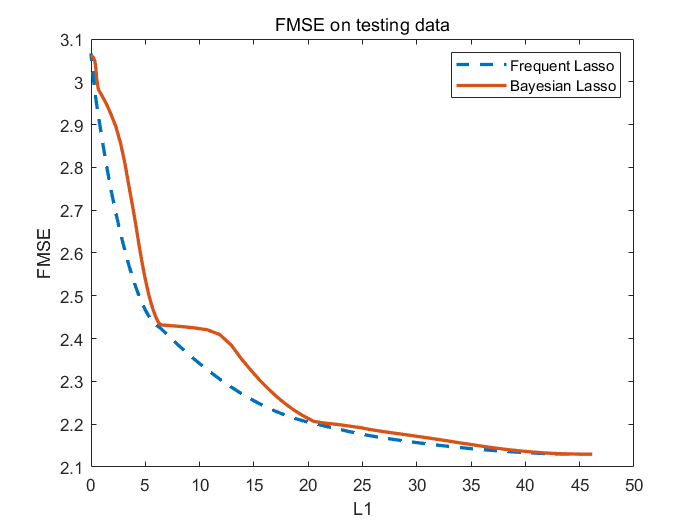

% comparison 
figure;
plot(L1Vals,fmseLasso_test,'LineWidth',2,'LineStyle','--');
hold on;
plot(L1Vals,fmseBayesLasso_test,'LineWidth',2,'LineStyle','-');
legend('Frequent Lasso','Bayesian Lasso');
xlabel('L1');
ylabel('FMSE');
title('FMSE on testing data');

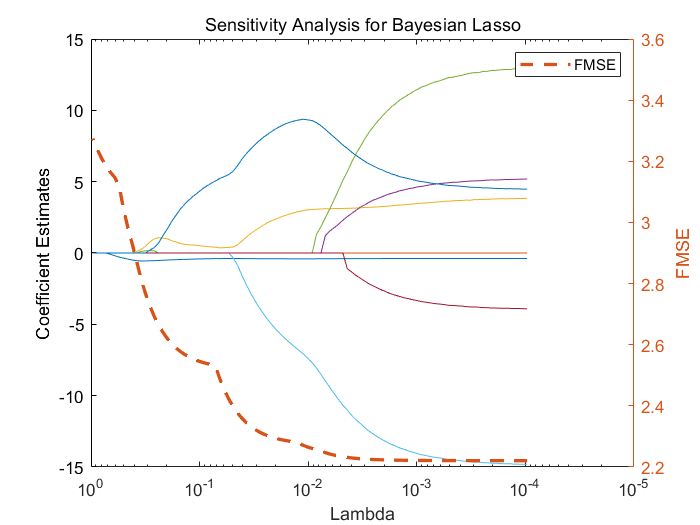


% sensitivity Analysis
figure;
semilogx(FitInfo.Lambda,BLCPlot(2:end,:))
xlabel('Lambda');
ylabel('Coefficient Estimates');
yyaxis right;
h_train = semilogx(FitInfo.Lambda,fmseLasso_train,'LineWidth',2,'LineStyle','--');
legend(h_train,'FMSE');
ylabel('FMSE');
set(gca,'XDir','reverse');
title('Sensitivity Analysis for Bayesian Lasso');

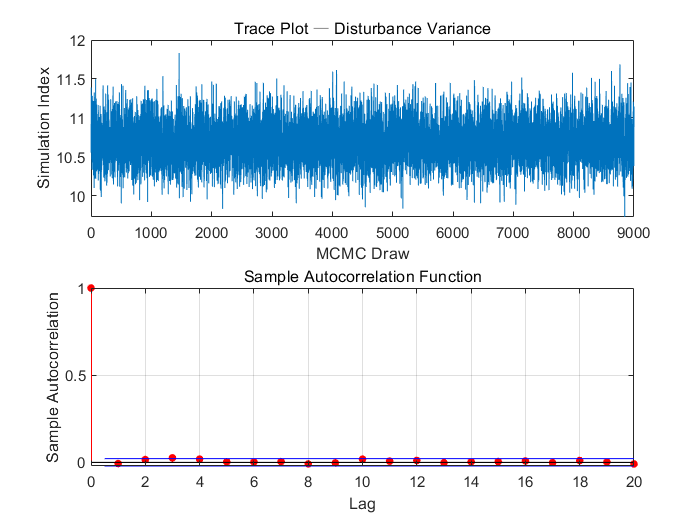

figure;
subplot(2,1,1);
plot(EstMdl.Sigma2Draws(1001:end));
title(['Trace Plot ' char(8212) ' Disturbance Variance']);
xlabel('MCMC Draw');
ylabel('Simulation Index');
subplot(2,1,2);
autocorr(EstMdl.Sigma2Draws(1001:end));

% effective sample size 
fprintf("ESS: %d\n",ESS(EstMdl.Sigma2Draws(1001:end))');

ESS: 8.017544e+03


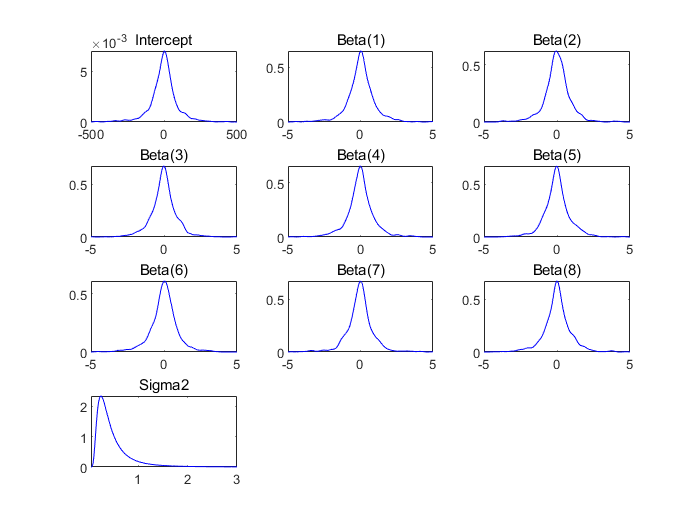


% for Lambda (frequeny lasso) we choose 0.6, for Baysian we choose 800
PriorMdl_lasso = bayeslm(p,'ModelType','lasso');
plot(PriorMdl_lasso);

PriorMdl_lasso.Lambda = 1000;
PosteriorMdl_lasso = estimate(PriorMdl_lasso,X_train,y_train);

Method: lasso MCMC sampling with 10000 draws
Number of observations: 3133
Number of predictors:   9
 
           |   Mean     Std         CI95        Positive  Distribution 
-----------------------------------------------------------------------
 Intercept |  9.9182  0.0593  [ 9.803, 10.037]    1.000     Empirical  
 Beta(1)   | -0.0270  0.0261  [-0.095,  0.001]    0.051     Empirical  
 Beta(2)   |  0.0053  0.0076  [-0.004,  0.025]    0.785     Empirical  
 Beta(3)   |  0.0061  0.0083  [-0.004,  0.028]    0.800     Empirical  
 Beta(4)   |  0.0009  0.0047  [-0.008,  0.012]    0.570     Empirical  
 Beta(5)   |  0.0062  0.0086  [-0.004,  0.029]    0.798     Empirical  
 Beta(6)   |  0.0031  0.0059  [-0.006,  0.018]    0.701     Empirical  
 Beta(7)   |  0.0038  0.0064  [-0.005,  0.020]    0.731     Empirical  
 Beta(8)   |  0.0053  0.0076  [-0.004,  0.026]    0.783     Empirical  
 Sigma2    | 10.6645  0.2696  [10.149, 11.199]    1.000     Empirical  
 


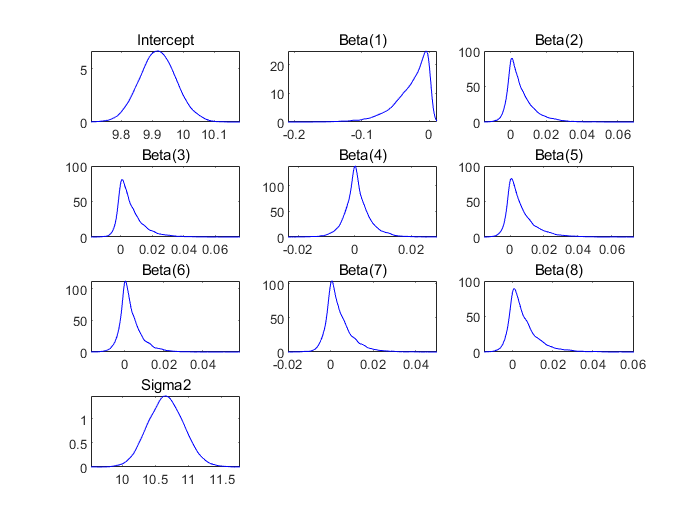

plot(PosteriorMdl_lasso);

fmse_train = sqrt(mean((y_train - pred_train).^2));
pred_test = forecast(PosteriorMdl_lasso,X_test);
fmse_test = sqrt(mean((y_test - pred_test).^2));
fprintf('train: %.3f, test: %.3f\n',fmse_train,fmse_test);

train: 2.239, test: 3.054
